%Input Training Data------------------------------------------------------------
%[y,Fs,bits] = wavread('filename')
[s1,Fs(1)] = audioread('./Training_Data/s1.wav');
[s2,Fs(2)] = audioread('./Training_Data/s2.wav');
[s3,Fs(3)] = audioread('./Training_Data/s3.wav');
[s4,Fs(4)] = audioread('./Training_Data/s4.wav');
[s5,Fs(5)] = audioread('./Training_Data/s5.wav');
[s6,Fs(6)] = audioread('./Training_Data/s6.wav');
[s7,Fs(7)] = audioread('./Training_Data/s7.wav');
[s8,Fs(8)] = audioread('./Training_Data/s8.wav');
[s9,Fs(9)] = audioread('./Training_Data/s9.wav');
[s10,Fs(10)]= audioread('./Training_Data/s10.wav');
[s11,Fs(11)] = audioread('./Training_Data/s11.wav');

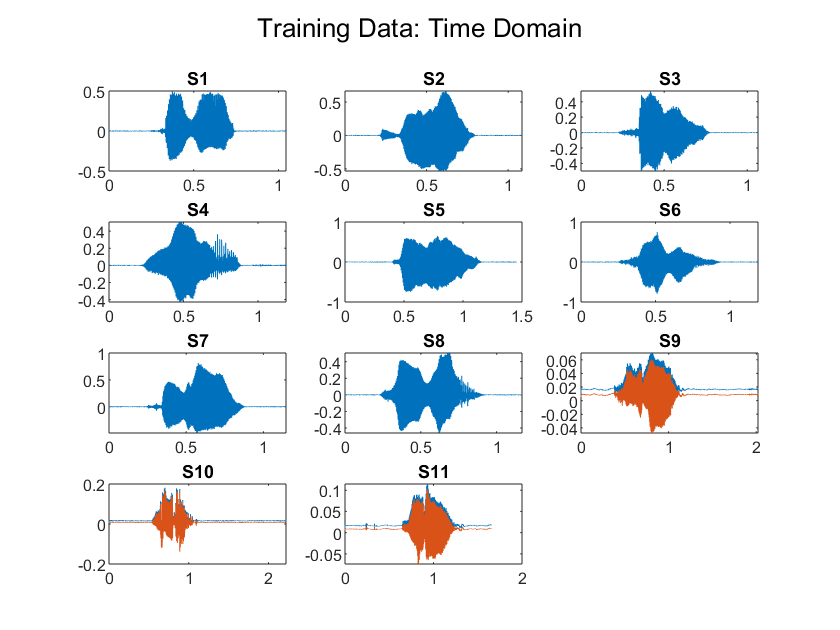

%Plot Training Data Time Domain------------------------------------------------------------
f = figure();
sgtitle('Training Data: Time Domain');

%generate Time Axis
time1 = [0:1/Fs(1):length(s1)*(1/Fs(1))-(1/Fs(1))];
time2 = [0:1/Fs(2):length(s2)*(1/Fs(2))-(1/Fs(2))];
time3 = [0:1/Fs(3):length(s3)*(1/Fs(3))-(1/Fs(3))];
time4 = [0:1/Fs(4):length(s4)*(1/Fs(4))-(1/Fs(4))];
time5 = [0:1/Fs(5):length(s5)*(1/Fs(5))-(1/Fs(5))];
time6 = [0:1/Fs(6):length(s6)*(1/Fs(6))-(1/Fs(6))];
time7 = [0:1/Fs(7):length(s7)*(1/Fs(7))-(1/Fs(7))];
time8 = [0:1/Fs(8):length(s8)*(1/Fs(8))-(1/Fs(8))];
time9 = [0:1/Fs(9):length(s9)*(1/Fs(9))-(1/Fs(9))];
time10 = [0:1/Fs(10):length(s10)*(1/Fs(10))-(1/Fs(10))];
time11 = [0:1/Fs(11):length(s11)*(1/Fs(11))-(1/Fs(11))];

%Plot Data
subplot(4,3,1);
plot(time1,s1);
title('S1');
subplot(4,3,2);
plot(time2,s2);
title('S2');
subplot(4,3,3);
plot(time3,s3);
title('S3');
subplot(4,3,4);
plot(time4,s4);
title('S4');
subplot(4,3,5);
plot(time5,s5);
title('S5');
subplot(4,3,6);
plot(time6,s6);
title('S6');
subplot(4,3,7);
plot(time7,s7);
title('S7');
subplot(4,3,8);
plot(time8,s8);
title('S8');
subplot(4,3,9);
plot(time9,s9);
title('S9');
subplot(4,3,10);
plot(time10,s10);
title('S10');
subplot(4,3,11);
plot(time11,s11);
title('S11');

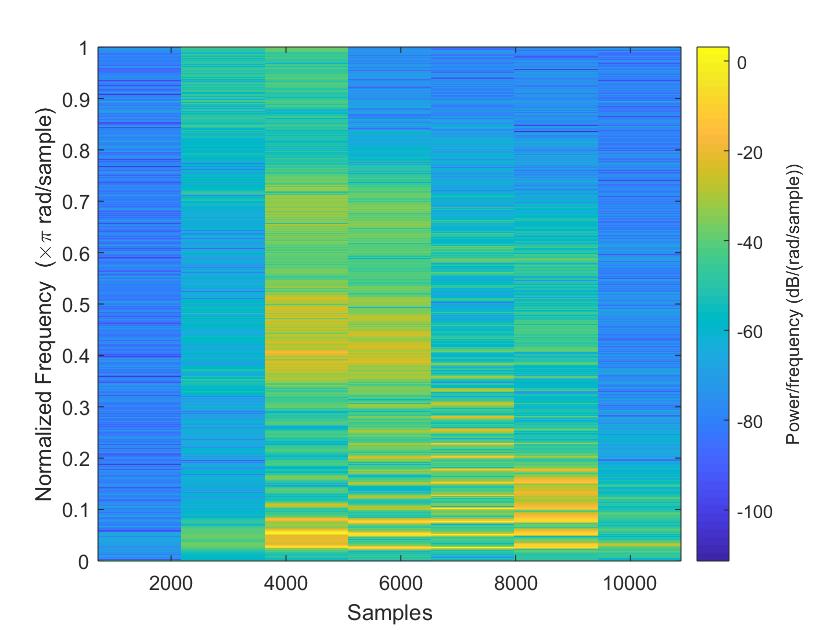

%Create Spectograms
f = figure();
title('Training Data: Spectograms')
spectrogram(s1,'yaxis');

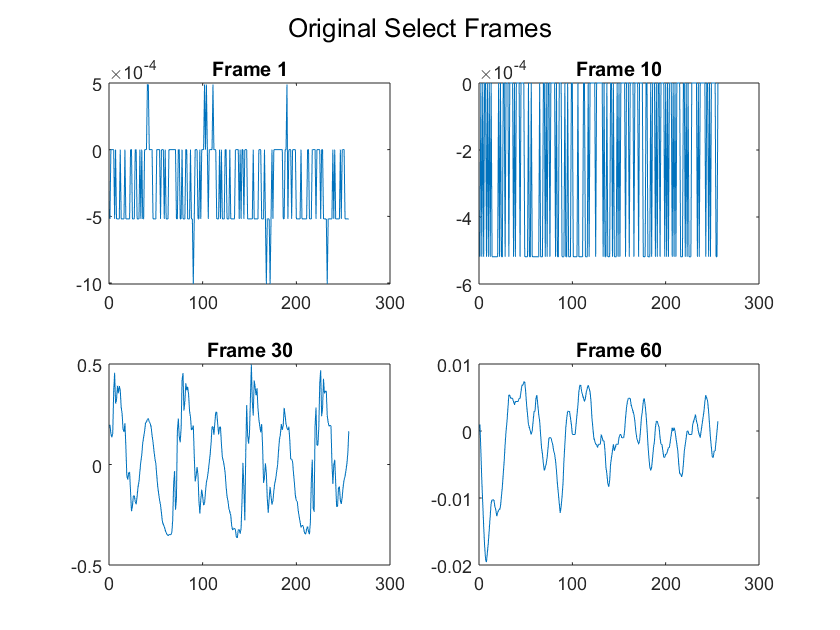

%Frame Blocking------------------------------------------------------------
N = 256;
M = 100;
s1length = length(s1);
i = 1;
count = 1;
while(i+N < s1length)
    s1frames(count,:) = s1(i:i+N-1);
    i = i + N - M;
    count = count + 1;
end

f2 = figure();
sgtitle('Original Select Frames')
subplot(2,2,1);
plot(s1frames(1,:));
title('Frame 1')
subplot(2,2,2);
plot(s1frames(10,:));
title('Frame 10')
subplot(2,2,3);
plot(s1frames(30,:));
title('Frame 30')
subplot(2,2,4);
plot(s1frames(60,:));
title('Frame 60')

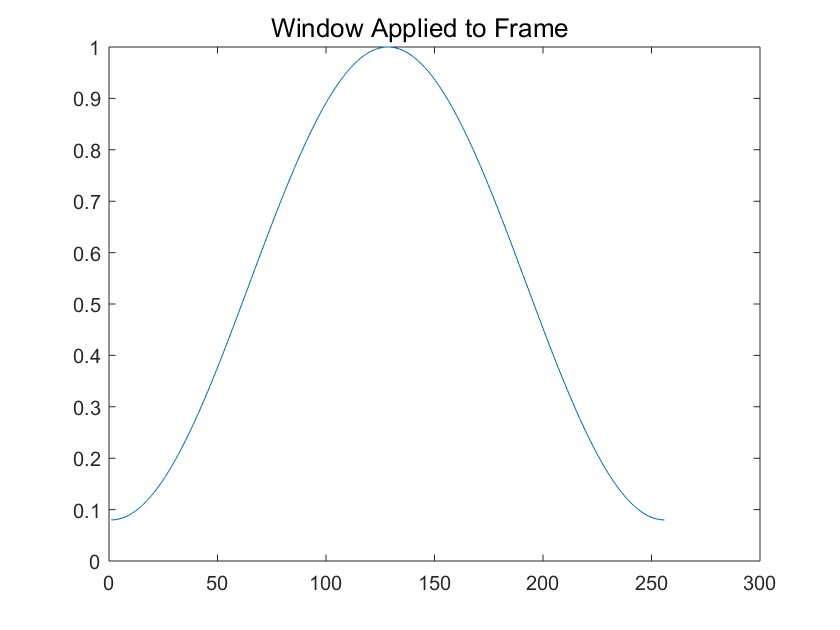

%Apply Window------------------------------------------------------------
%w(n) = 0.54 - 0.46cos(2pin/(N-1)),0<=n<=N-1
for i = [0:N-1]
    w(i+1) = 0.54 - 0.46*cos((2*pi*i)/(N-1));
end
f2 = figure();
sgtitle('Window Applied to Frame');
plot(w);



s1framecount = length(s1frames(:,1));
disp(s1framecount);

    83



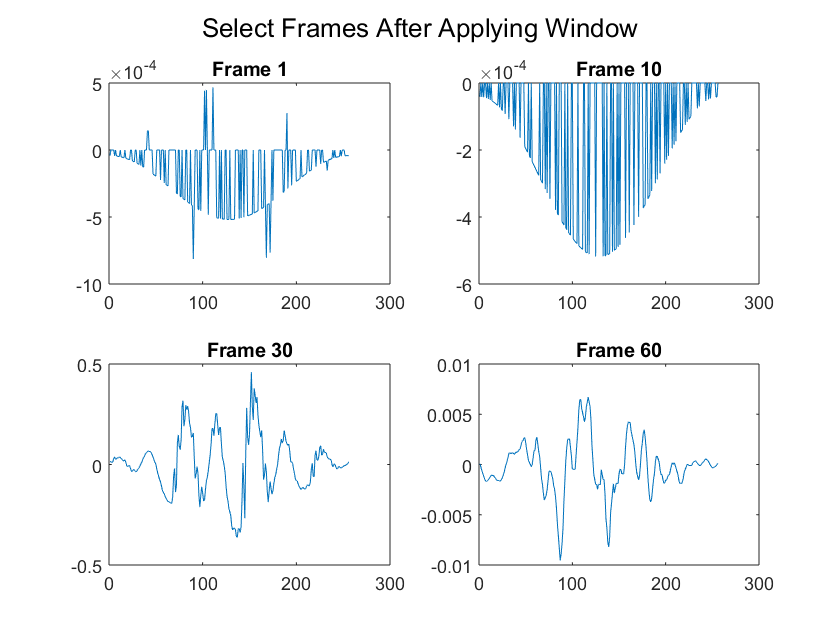


for i = [1:s1framecount]
    s1framesWindow(i,:) = w.*s1frames(i,:);
end

f2 = figure();
sgtitle('Select Frames After Applying Window')
subplot(2,2,1);
plot(s1framesWindow(1,:));
title('Frame 1')
subplot(2,2,2);
plot(s1framesWindow(10,:));
title('Frame 10')
subplot(2,2,3);
plot(s1framesWindow(30,:));
title('Frame 30')
subplot(2,2,4);
plot(s1framesWindow(60,:));
title('Frame 60')


% %Hamming Window

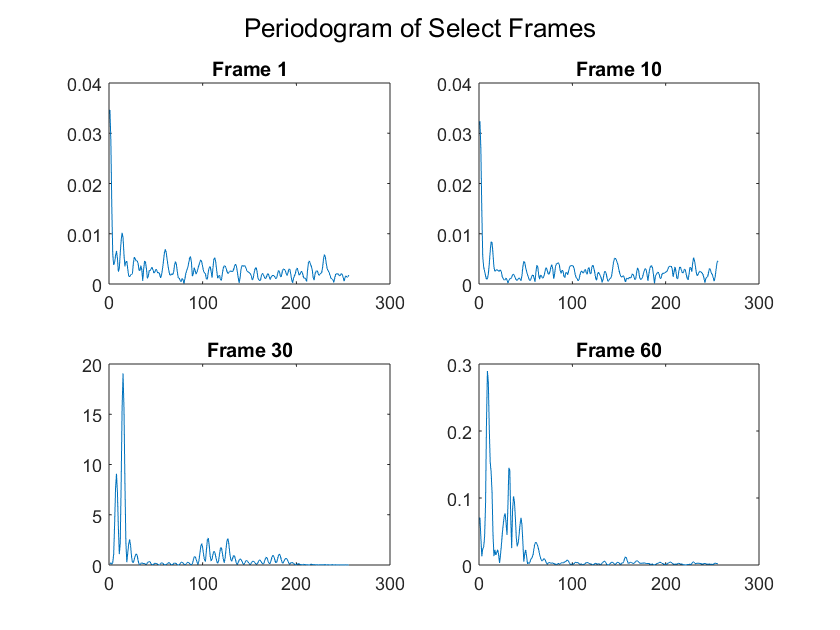

%FFT (Periodogram)------------------------------------------------------------
for i = [1:s1framecount]
    s1framesWindowFFT512(i,:) = fft(s1framesWindow(i,:),512);
    s1framesWindowFFT256(i,:) = s1framesWindowFFT512(i,[1:256]);
end
f2 = figure();
sgtitle('Periodogram of Select Frames')
subplot(2,2,1);
plot(abs(s1framesWindowFFT256(1,:)));
title('Frame 1')
subplot(2,2,2);
plot(abs(s1framesWindowFFT256(10,:)));
title('Frame 10')
subplot(2,2,3);
plot(abs(s1framesWindowFFT256(30,:)));
title('Frame 30')
subplot(2,2,4);
plot(abs(s1framesWindowFFT256(60,:)));
title('Frame 60')

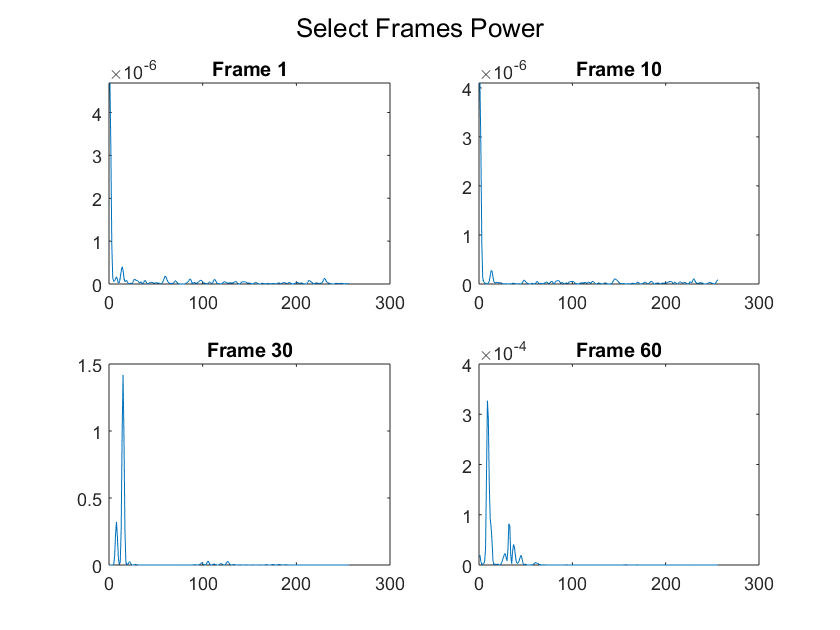

%Power------------------------------------------------------------
for i = [1:s1framecount]
    s1framespower(i,:) = (1/N)*(abs(s1framesWindowFFT256(i,:)).^2);
end
f2 = figure();
sgtitle('Select Frames Power')
subplot(2,2,1);
plot(s1framespower(1,:));
title('Frame 1')
subplot(2,2,2);
plot(s1framespower(10,:));
title('Frame 10')
subplot(2,2,3);
plot(s1framespower(30,:));
title('Frame 30')
subplot(2,2,4);
plot(s1framespower(60,:));
title('Frame 60')

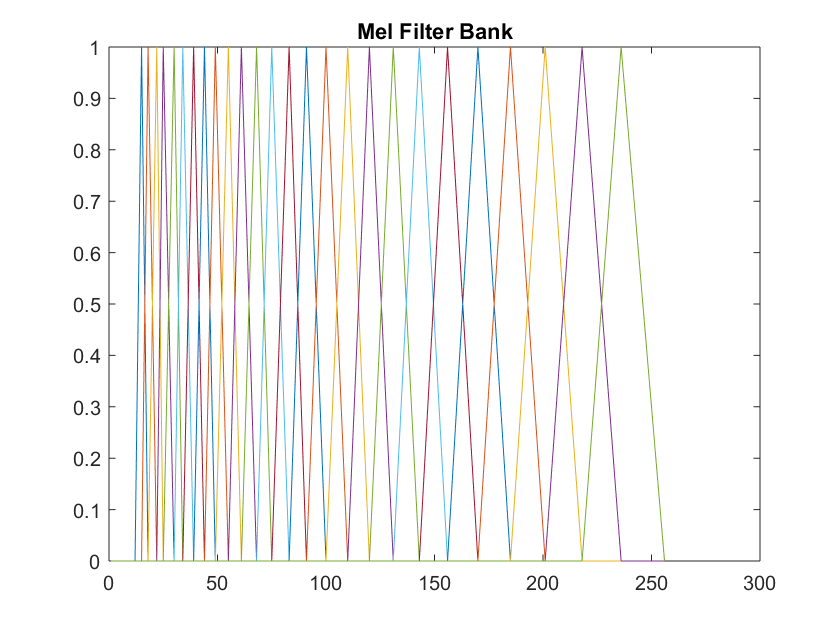

%Generate mN Filters----------------------------------------
mN = 26;
lowerFreqF = 300;%Hz
upperFreqF = 6250;%Hz
lowerFreqM = 1125*log(1+(lowerFreqF/700));%lower in mels
upperFreqM = 1125*log(1+(upperFreqF/700));%upper in mels
%Generate mN points inbetween lower upper in mels scale
m = linspace(lowerFreqM,upperFreqM,mN+2);
h = 700*(exp(m/1125)-1);%get back into hz scale (should be between 300-8000Hz)
%get hz to closest fft bin
%f(i) = floor((nfft+1)*h(i)/samplerate)
f = floor(((512+1)*h)/Fs(1));
for i = [1:mN]%Generate mN filters
    H(i,[1:f(i)]) = 0;
    for k = [f(i):f(i+1)]
    %H(i,[f(i):f(i+1)]) = (i-f(i))/(f(i+1)-f(i));
        H(i,k) = (k-f(i))/(f(i+1)-f(i));
    end
    for k = [f(i+1):f(i+2)]
    %H(i,[f(i+1):f(i+2)]) = (f(i+2)-i)/(f(i+2)-f(i+1));
        H(i,k) = (f(i+2)-k)/(f(i+2)-f(i+1));
    end
    
    H(i,[f(i+2):N]) = 0;
end
f2 = figure();
for i = [1:mN]
    plot([1:N],H(i,:));
    hold on;
end
title('Mel Filter Bank');
hold off;

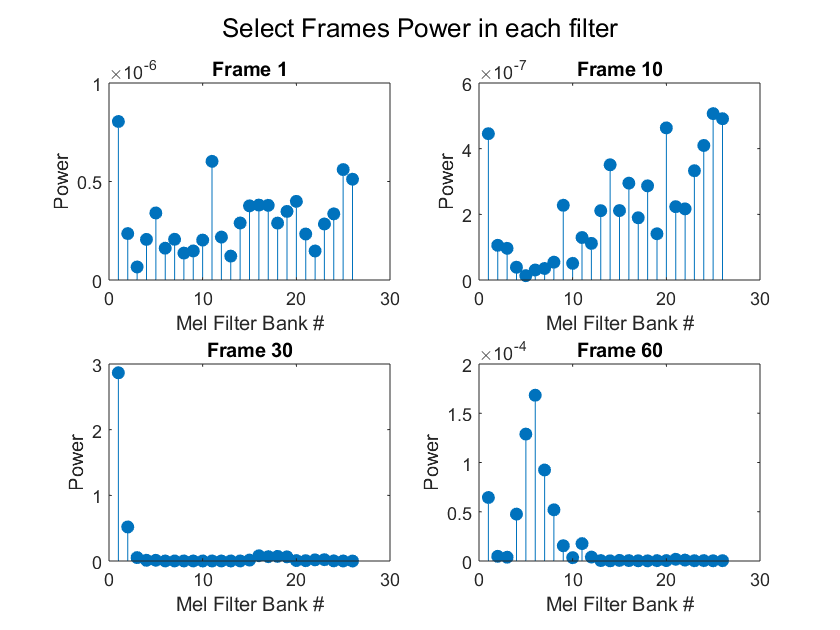

%Power of Signal in each filter---------------------------------------
for f = [1:83]%for each frame
    for i = [1:mN]
        multPowerFilter = H(i,:).*s1framespower(f,:);
        melFilterPower(f,i) = sum(multPowerFilter);
    end
end
f2 = figure();
sgtitle('Select Frames Power in each filter')
subplot(2,2,1);
stem([1:mN],melFilterPower(1,[1:mN]),'filled');
title('Frame 1')
xlabel('Mel Filter Bank #');
ylabel('Power');
subplot(2,2,2);
stem([1:mN],melFilterPower(10,[1:mN]),'filled');
title('Frame 10')
xlabel('Mel Filter Bank #');
ylabel('Power');
subplot(2,2,3);
stem([1:mN],melFilterPower(30,[1:mN]),'filled');
title('Frame 30')
xlabel('Mel Filter Bank #');
ylabel('Power');
subplot(2,2,4);
stem([1:mN],melFilterPower(60,[1:mN]),'filled');
title('Frame 60')
xlabel('Mel Filter Bank #');
ylabel('Power');

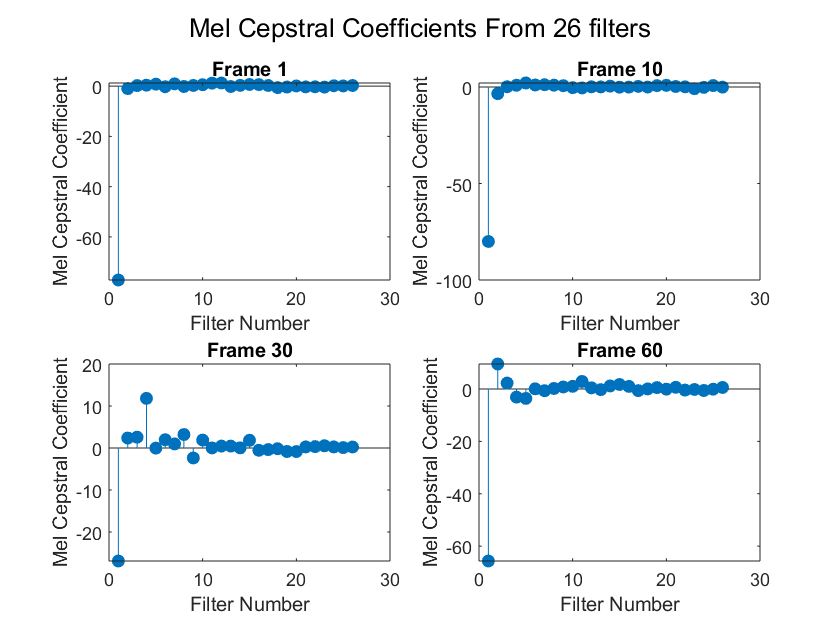

%Cepstrum------------------------------------------------------------
for f = [1:83]
    melFilterPowerLog(f,:) = log(melFilterPower(f,:));%take log
    cepstralCoeff(f,:) = dct(melFilterPowerLog(f,:));
end


%plot frame 1 dct magnitudes from the mn(26) filters
f2 = figure();
sgtitle('Mel Cepstral Coefficients From 26 filters')

subplot(2,2,1);
stem([1:mN],cepstralCoeff(1,[1:mN]),'filled');
title('Frame 1');
xlabel('Filter Number');
ylabel('Mel Cepstral Coefficient');

subplot(2,2,2);
stem([1:mN],cepstralCoeff(10,[1:mN]),'filled');
title('Frame 10');
xlabel('Filter Number');
ylabel('Mel Cepstral Coefficient');

subplot(2,2,3);
stem([1:mN],cepstralCoeff(30,[1:mN]),'filled');
title('Frame 30');
xlabel('Filter Number');
ylabel('Mel Cepstral Coefficient');

subplot(2,2,4);
stem([1:mN],cepstralCoeff(60,[1:mN]),'filled');
title('Frame 60');
xlabel('Filter Number');
ylabel('Mel Cepstral Coefficient');

%localFunctions
